% Main folder path containing subfolders (each representing a class)
mainFolder = 'D:\MSM_TMI\Image_openMV-granulosa\openMV_granulosa';

% Get list of all subfolders (excluding '.' and '..')
subfolders = dir(mainFolder);
subfolders = subfolders([subfolders.isdir] & ~ismember({subfolders.name}, {'.', '..'}));

% Initialize results table
results = table('Size', [0 8], ...
    'VariableTypes', {'string', 'string', 'double', 'double', 'double', 'double', 'double', 'double'}, ...
    'VariableNames', {'Class', 'ImageName', 'Entropy', 'MeanIntensity', 'MedianIntensity', 'Contrast', 'Energy', 'Correlation'});

% Loop over subfolders (classes)
for k = 1:length(subfolders)
    className = subfolders(k).name;
    classPath = fullfile(mainFolder, className);
    
    imageFiles = dir(fullfile(classPath, '*.bmp')); % or *.jpg, *.tif, etc.
    
    for i = 1:length(imageFiles)
        imgName = imageFiles(i).name;
        imgPath = fullfile(classPath, imgName);
        img = imread(imgPath);
        
        % Convert to grayscale if RGB
        if size(img, 3) == 3
            imgGray = rgb2gray(img);
        else
            imgGray = img;
        end
        
        % Compute features
        ent = entropy(imgGray);                       % Entropy
        mn = mean(imgGray(:));                        % Mean intensity
        med = median(double(imgGray(:)));             % Median intensity
        
        % GLCM and its features
        glcm = graycomatrix(imgGray, 'Offset', [0 1]); % Horizontal (0°)
        stats = graycoprops(glcm, {'Contrast', 'Energy', 'Correlation'});
        
        % Append to results table
        results = [results; {
            string(className), string(imgName), ent, mn, med, ...
            stats.Contrast, stats.Energy, stats.Correlation
        }];
    end
end

% Display results
disp(results);

     Class     ImageName    Entropy    MeanIntensity    MedianIntensity    Contrast    Energy     Correlation
    _______    _________    _______    _____________    _______________    ________    _______    ___________

    "blue"      "1.bmp"     5.6847        75.013               72           0.15372    0.42635      0.73503  
    "blue"      "2.bmp"     6.1085        115.76              120           0.21795    0.28253      0.75926  
    "blue"      "3.bmp"     5.6789        72.759               72           0.17222    0.42133      0.67697  
    "blue"      "4.bmp"     6.2305        102.12               98           0.23039    0.24743      0.76951  
    "blue"      "5.bmp"     5.5603        73.815               73  


% Optional: Save to CSV
writetable(results, 'image_features_results.csv');

%% 📊 Plotting Boxplots for Each Feature by Class
featuresToPlot = {'Entropy', 'MeanIntensity', 'MedianIntensity', ...
                  'Contrast', 'Energy', 'Correlation'};

for i = 1:length(featuresToPlot)
    figure;
    boxplot(results.(featuresToPlot{i}), results.Class, 'Notch', 'on');
    %title(['Boxplot of ', featuresToPlot{i}, ' by Class']);
    xlabel('Color Channel');
    ylabel(featuresToPlot{i});

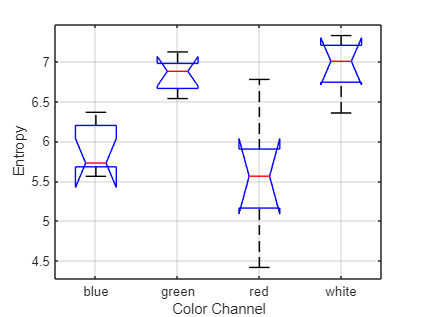

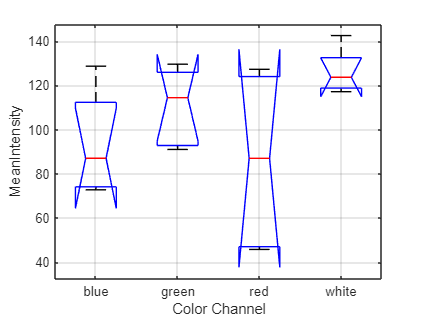

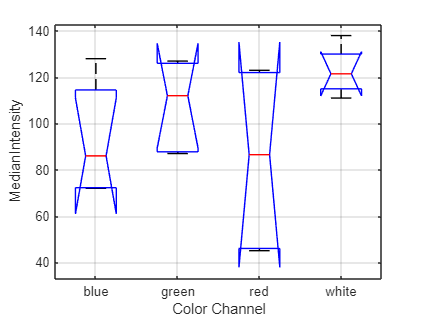

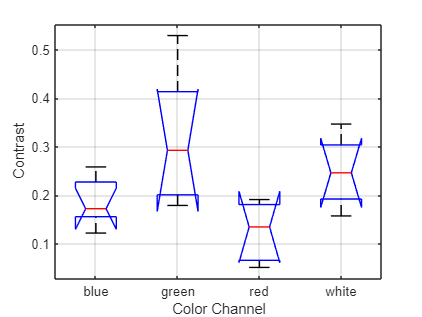

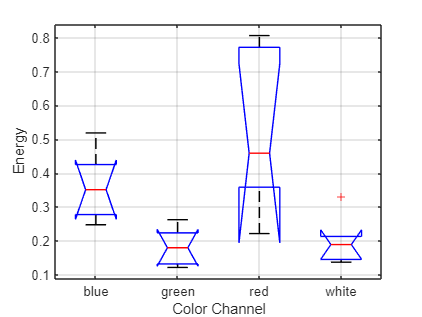

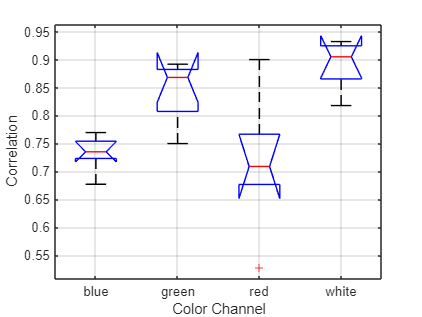

    grid on;
end


% Extract feature matrix (only numerical features)
features = [results.Entropy, results.MeanIntensity, results.MedianIntensity, ...
            results.Contrast, results.Energy, results.Correlation];

% Convert class labels to categorical for coloring
classLabels = categorical(results.Class);

% Perform PCA
[coeff, score, latent, tsquared, explained] = pca(features);

% Display variance explained by each PC
disp('Explained variance by principal components (%):');

Explained variance by principal components (%):


disp(explained);

   99.3267
    0.6535
    0.0186
    0.0007
    0.0004
    0.0001



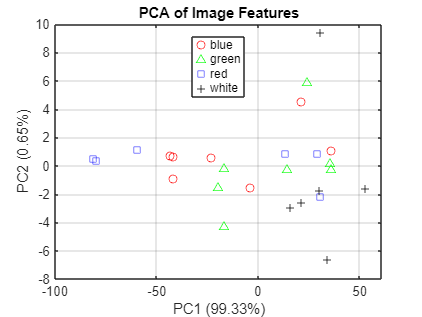


% 2D Scatter Plot of the first two PCs
figure;
gscatter(score(:,1), score(:,2), classLabels, 'rgbk', 'o^s+');
xlabel(['PC1 (', num2str(round(explained(1),2)), '%)']);
ylabel(['PC2 (', num2str(round(explained(2),2)), '%)']);
title('PCA of Image Features');
legend('Location', 'best');
grid on;


% Optional: 3D Scatter Plot
figure;
scatter3(score(:,1), score(:,2), score(:,3), 70, classLabels, 'filled');
xlabel(['PC1 (', num2str(round(explained(1),2)), '%)']);
ylabel(['PC2 (', num2str(round(explained(2),2)), '%)']);
zlabel(['PC3 (', num2str(round(explained(3),2)), '%)']);
title('3D PCA of Image Features');
legend(unique(classLabels), 'Location', 'best');

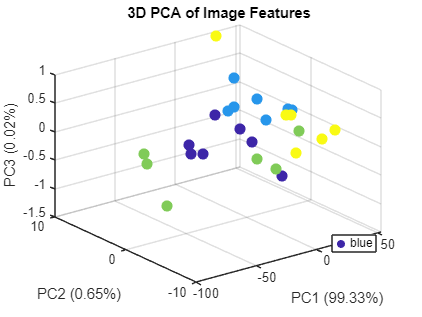

grid on;


classes = unique(results.Class);
featuresToTest = {'Entropy', 'MeanIntensity', 'MedianIntensity', ...
                  'Contrast', 'Energy', 'Correlation'};

for i = 1:length(featuresToTest)
    fprintf('\n=== Shapiro-Wilk Test for %s ===\n', featuresToTest{i});
    
    for j = 1:length(classes)
        className = classes(j);
        featureData = results{results.Class == className, featuresToTest{i}};
        
        [h, p] = dwtest(featureData, 0.05);  % h=1 => reject normality
        
        if h == 1
            conclusion = 'NOT normal';
        else
            conclusion = 'Normal';
        end
        
        fprintf('Class: %-6s | p = %.4f | %s\n', className, p, conclusion);
    end
end


=== Shapiro-Wilk Test for Entropy ===


Class: blue   | p = 0.0089 | Normal
Class: green  | p = 0.0020 | Normal
Class: red    | p = 0.0280 | Normal
Class: white  | p = 0.0041 | Normal



=== Shapiro-Wilk Test for MeanIntensity ===


Class: blue   | p = 0.1101 | Normal
Class: green  | p = 0.0222 | Normal
Class: red    | p = 0.3015 | Normal
Class: white  | p = 0.0113 | Normal



=== Shapiro-Wilk Test for MedianIntensity ===


Class: blue   | p = 0.1235 | Normal
Class: green  | p = 0.0389 | Normal
Class: red    | p = 0.2967 | Normal
Class: white  | p = 0.0127 | Normal



=== Shapiro-Wilk Test for Contrast ===


Class: blue   | p = 0.1875 | Normal
Class: green  | p = 0.2711 | Normal
Class: red    | p = 0.4343 | Normal
Class: white  | p = 0.1481 | Normal



=== Shapiro-Wilk Test for Energy ===


Class: blue   | p = 0.2151 | Normal
Class: green  | p = 0.1860 | Normal
Class: red    | p = 0.3566 | Normal
Class: white  | p = 0.1668 | Normal



=== Shapiro-Wilk Test for Correlation ===


Class: blue   | p = 0.0049 | Normal
Class: green  | p = 0.0040 | Normal
Class: red    | p = 0.0214 | Normal
Class: white  | p = 0.0036 | Normal



=== ANOVA for Entropy ===


p-value: 0.0000


Significant difference detected. Running post-hoc test...



=== ANOVA for MeanIntensity ===


p-value: 0.0373


Significant difference detected. Running post-hoc test...



=== ANOVA for MedianIntensity ===


p-value: 0.0587


No significant difference between class means.



=== ANOVA for Contrast ===


p-value: 0.0038


Significant difference detected. Running post-hoc test...



=== ANOVA for Energy ===


p-value: 0.0005


Significant difference detected. Running post-hoc test...



=== ANOVA for Correlation ===


p-value: 0.0003


Significant difference detected. Running post-hoc test...


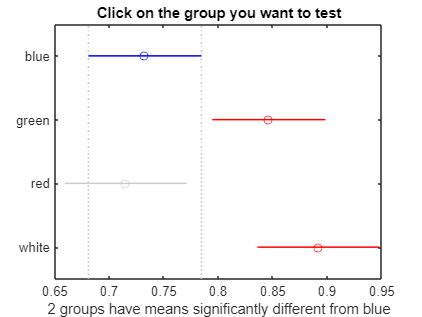


% List of features to test
featuresToTest = {'Entropy', 'MeanIntensity', 'MedianIntensity', ...
                  'Contrast', 'Energy', 'Correlation'};

% Loop over each feature
for i = 1:length(featuresToTest)
    featureName = featuresToTest{i};
    fprintf('\n=== ANOVA for %s ===\n', featureName);

    % Extract feature values and class labels
    featureData = results{:, featureName};
    groupLabels = results.Class;

    % Perform one-way ANOVA
    [p, tbl, stats] = anova1(featureData, groupLabels, 'off');  % 'off' hides the default plot

    fprintf('p-value: %.4f\n', p);
    
    % If significant, perform post-hoc multiple comparison test
    if p < 0.05
        fprintf('Significant difference detected. Running post-hoc test...\n');
        multcompare(stats, 'Display', 'on');  % Set 'on' to show GUI
    else
        fprintf('No significant difference between class means.\n');
    end
end

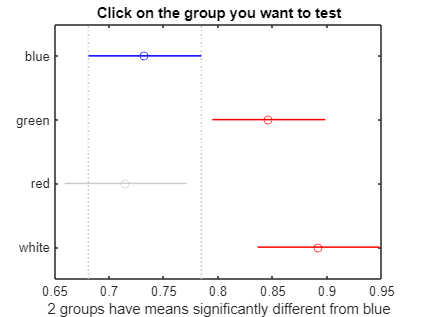

% For example, after each significant ANOVA:
multcompare(stats); % This opens a GUI figure showing pairwise class differences